# Lab 5

Loading data...

h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_250_500.h5")

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

*Notes on data:*

The Large Hadron Collider (LHC) is an instrument used to accelerate bunches of protons around a ring at close to the speed of light. The ATLAS detector consists of many solenoids, calorimeters, spectrometers, and other systems used to detect collisions and collect data about them. Conventionally, the particles travel along the 'z-axis'. 

A jet is a collection of particles that go in the same direction within the detector, and it must be defined by experimental observables such as 4-momentum. 

In this lab, the Higgs data represents simulated data of a Higgs boson decay detected in the LHC and the qcd data is background data contamination from other potential collisions. 

For the Higgs data, $N_{\textrm{higgs}} =100$ for expected yields; for qcd data, $N_{\textrm{qcd}} =20000$ for expected yields; all data has low $p_T$ such that $p_T \;\epsilon \;\left\lbrack 250,500\right\rbrack$.

## Variables:

My data includes 14 rows, each containing the data corresponding to a specific feature. Here is a list of the features and their relevance:

'pt', ${\mathit{\mathbf{p}}}_T =\left(p_x ,p_y \right)=$ transverse momentum, the momentum of the particle. This data gives only the vector sum of the components, not the values of the components themselves. 

'eta', $\eta =\mathrm{ln}\;\mathrm{tan}\left(\frac{\theta }{2}\right)=$ pseudorapidity, a geometric quantity which is a function of the polar angle $\theta$.

'phi', $\phi =$ azithumal angle, measured around the z-axis of the beam. 

'mass', $m=$ mass of the particle. The mass of the Higgs boson is $m_h =125\ldotp 09\pm 0\ldotp 3$GeV. 

'ee2', $e_2^{\left(\beta \right)} =\frac{E_{\mathrm{CF2}} \left(\beta \right)}{E_{\mathrm{CF1}} {\left(\beta \right)}^2 }=$ ratio of the 2-point** energy correlation function and the 1-point* energy correlation function squared. 

'ee3', $e_3^{\left(\beta \right)} =\frac{E_{\mathrm{CF3}} \left(\beta \right)}{E_{\mathrm{CF1}} {\left(\beta \right)}^3 }=$ ratio of the 3-point*** energy correlation function and the 1-point energy correlation function cubed. 

'd2', $D_2^{\left(\beta \right)} =\frac{e_3^{\left(\beta \right)} }{{\left(e_2^{\left(\beta \right)} \right)}^3 }=$ a dimensionless variable which is the ratio of 'ee3' and 'ee2' cubed. Useful in identifying two-body structures in jets. $\beta =$ 1 or 2, typically. 

'angularity', $\tau_a^{\sim } \left(R,p_T \right)=\frac{1}{m_J }\sum_{i\epsilon \mathrm{jet}} \omega_i \;{\mathrm{sin}}^a \left(\frac{\pi \theta_i }{2R}\right){\left\lbrack 1-\mathrm{cos}\left(\frac{\pi \theta_i }{2R}\right)\right\rbrack }^{1-a} =$ angularity, a calss of jet shapes which is a function of jet dimension $R$ and transverse momentum. Angularity also depends on the polar angle $\theta$ and the mass of the jet $m_J$. 

't1', $\tau_1 =$ 1-subjettiness

't2', $\tau_2 =$ 2-subjettiness

't3', $\tau_3 =$ 3-subjettiness

't21', $\tau_{21} =\frac{\tau_2 }{\tau_1 }=$ ratio of 2- and 1-subjettiness.

 't32', $\tau_{32} =\frac{\tau_3 }{\tau_2 }=$ ratio of 3- and 2-subjettiness.

'KtDeltaR', $k_t \Delta R$; $\Delta R=\sqrt{{\left(\Delta \eta \right)}^2 +{\left(\Delta \phi \right)}^2 }=$ angular distance, or angular separation. Used in jet calculations. Depends on both polar and azithumal angles. 

*(end of variables)*

* $E_{\mathrm{CF1}} \left(\beta \right)=\sum_{i\epsilon J} p_{T_i }$

** $E_{\mathrm{CF2}} \left(\beta \right)=\sum_{i<j\epsilon J} p_{T_i } \;p_{T_j } \;{\left(\Delta R_{\mathrm{ij}} \right)}^{\beta }$

*** $E_{\mathrm{CF3}} \left(\beta \right)=\sum_{i<j<k\epsilon J} p_{T_i } \;p_{T_j } \;p_{T_k } \;{\left(\Delta R_{\mathrm{ij}} \;\Delta R_{\mathrm{ik}} \;\Delta R_{\mathrm{jk}} \right)}^{\beta }$

*Setup of each individual variable for both sets: *

pt_h = higgs(1,:);
eta_h = higgs(2,:);
phi_h = higgs(3,:);
mass_h = higgs(4,:);
ee2_h = higgs(5,:);
ee3_h = higgs(6,:);
d2_h = higgs(7,:);
angularity_h = higgs(8,:);
t1_h = higgs(9,:);
t2_h = higgs(10,:);
t3_h = higgs(11,:);
t21_h = higgs(12,:);
t32_h = higgs(13,:);
KtDeltaR_h = higgs(14,:);

pt_q = qcd(1,:);
eta_q = qcd(2,:);
phi_q = qcd(3,:);
mass_q = qcd(4,:);
ee2_q = qcd(5,:);
ee3_q = qcd(6,:);
d2_q = qcd(7,:);
angularity_q = qcd(8,:);
t1_q = qcd(9,:);
t2_q = qcd(10,:);
t3_q = qcd(11,:);
t21_q = qcd(12,:);
t32_q = qcd(13,:);
KtDeltaR_q = qcd(14,:);

- Do all features provide discrimination power between signal and background?

- Are there correlations among these features?

- Compute expected discovery sensitivity by normalizing each sample appropriately.

- Develop a plan to optimize the discovery sensitivity by applying selections to these features.

## 1. Discrimination Power Between Signal and Background

In this section I will compare the Higgs and qcd datasets for each variable. 

% histogram(pt_h,'Normalization','pdf')
% hold on
% histogram(pt_q,'Normalization','pdf')
% title('Transverse Momentum Signal vs. Background')
% xlabel('pT')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

The distributions of the histograms for pT are very distinct between pT = (400,500). The Higgs data peaks sharply around pT = 475 while the background contamination maintains lower values and has a more gentle slope. 

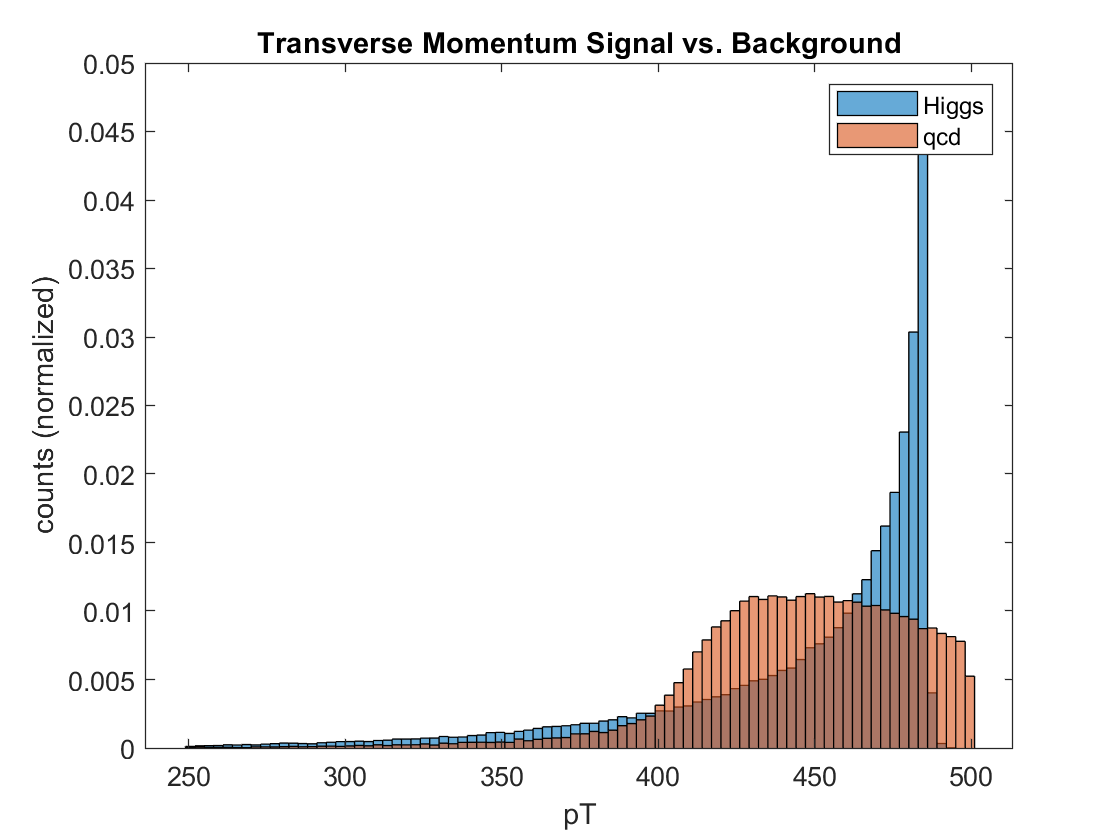

% histogram(eta_h,'Normalization','pdf')
% hold on
% histogram(eta_q,'Normalization','pdf')

% title('Pseudorapidity Signal vs. Background')
% xlabel('eta')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

Both datasets for pseudorapidity look vaguely gaussian in shape. They seem to be distinguishable, however, since the Higgs data is tall and narrow as opposed to the qcd short and wide distribution. 

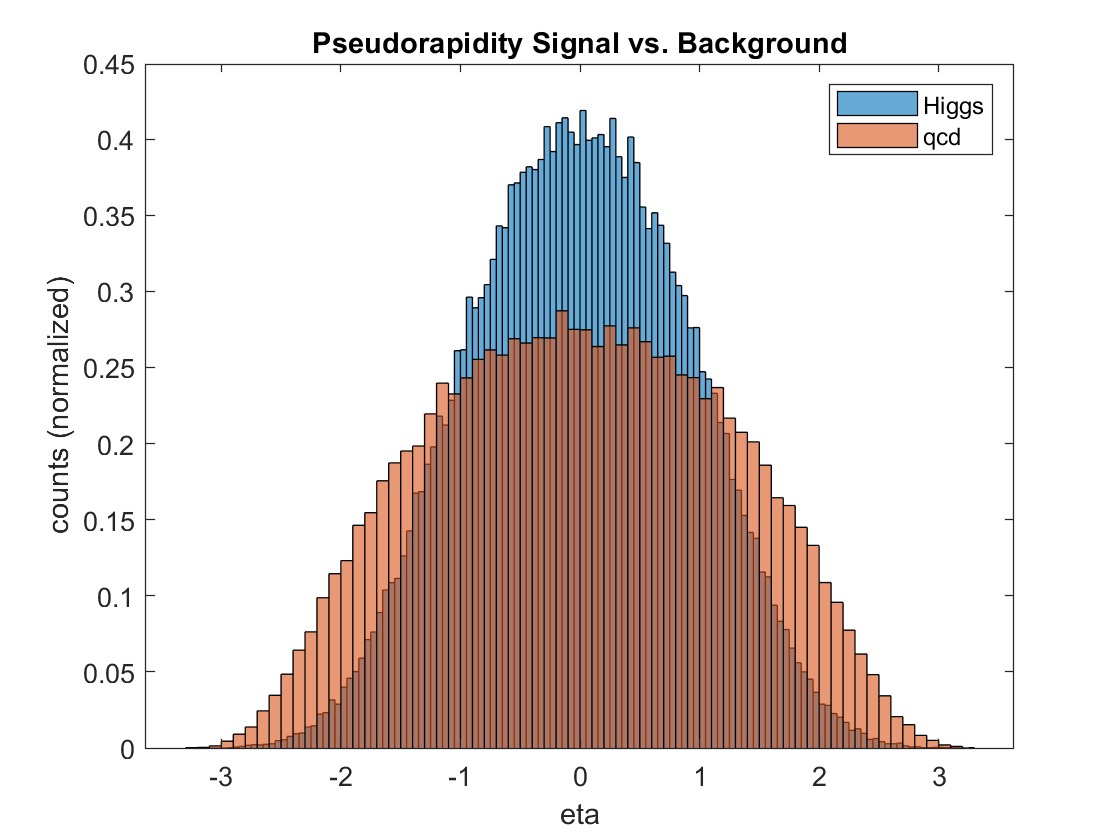

% histogram(phi_h)
% hold on
% histogram(phi_q)
% title('Azithumal Angle Signal vs. Background')
% xlabel('phi (radians)')

% ylabel('counts')
% legend('Higgs','qcd')
% hold off

The datasets for the azithumal angle overlap almost completely. There is no discrimination between the Higgs and qcd datasets. 

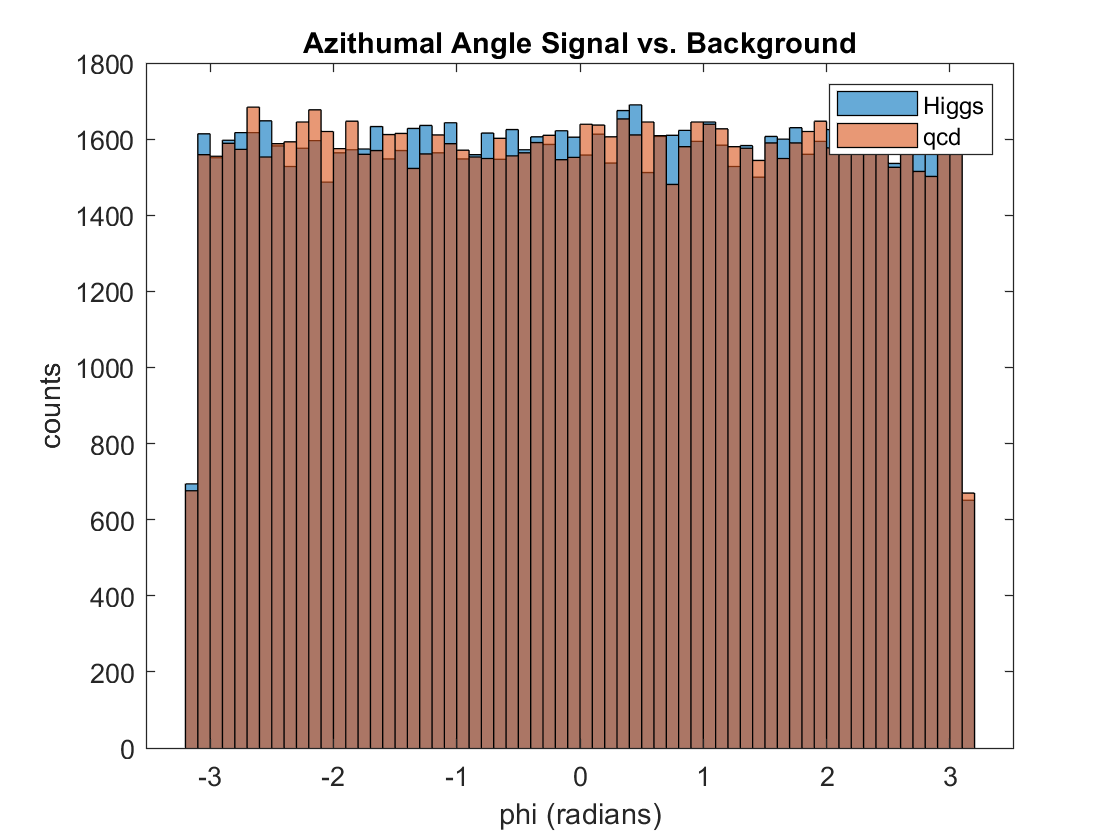

% histogram(mass_h)
% hold on
% histogram(mass_q)
% title('Mass Signal vs. Background')
% xlabel('mass (GeV)')
% ylabel('counts')
% legend('Higgs','qcd')

% hold off

The mass data is highly distinguishable between the two datasets. The Higgs data peaks extremely sharply at around 125 GeV as expected. The qcd background is a wider, low-sloped distribution. 

% histogram(ee2_h)
% hold on
% histogram(ee2_q)
% title('ee2 Signal vs. Background')
% xlabel('ee2')
% ylabel('counts')
% legend('Higgs','qcd')
% hold off

The ratio of 2-point and 1-point energy correlation functions are distinguishable. The Higgs and background data have significantly different peak values and overall are very different distributions. 

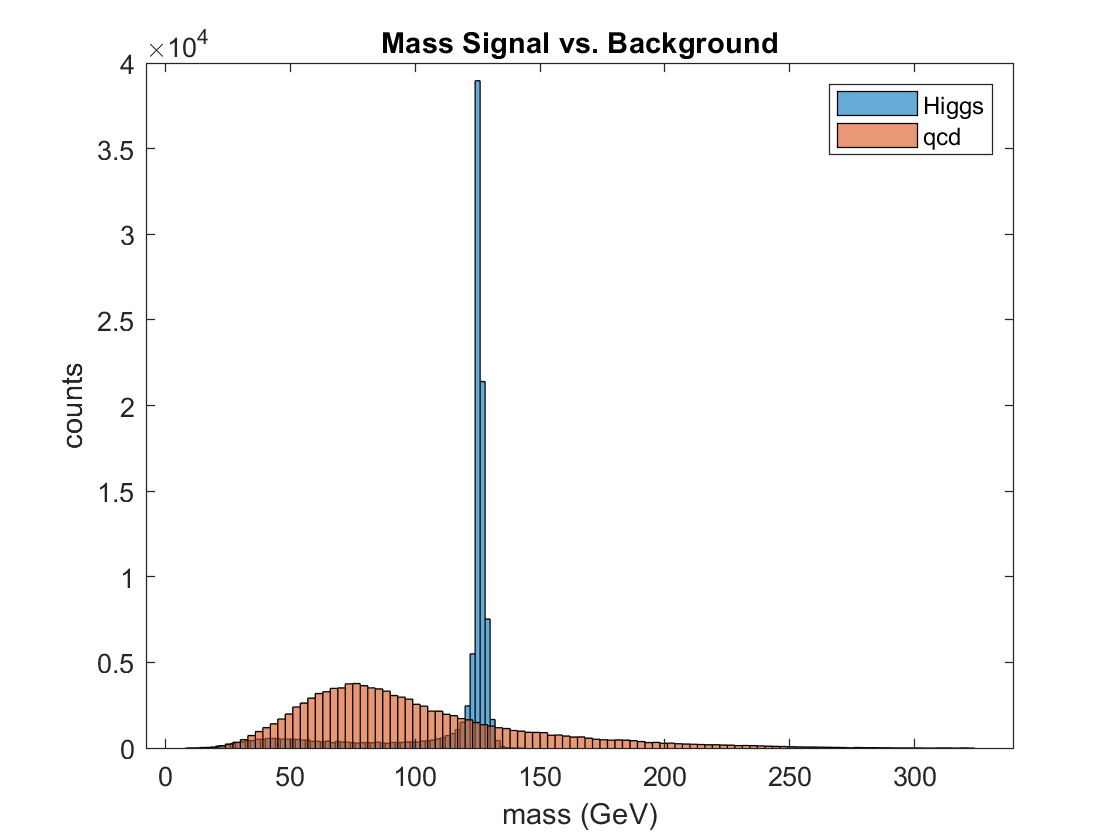

% histogram(ee3_h,'Normalization','pdf')

% hold on
% histogram(ee3_q,'Normalization','pdf')
% title('ee3 Signal vs. Background')
% xlabel('ee3')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

The ratios of 3-point and 1-point energy correlation functions are far less distinguishable than their ee2 counterparts. Both datasets have a sharp peak near zero then a small tail to the right. The qcd data is slightly sharper, but discrimination may prove difficult. 

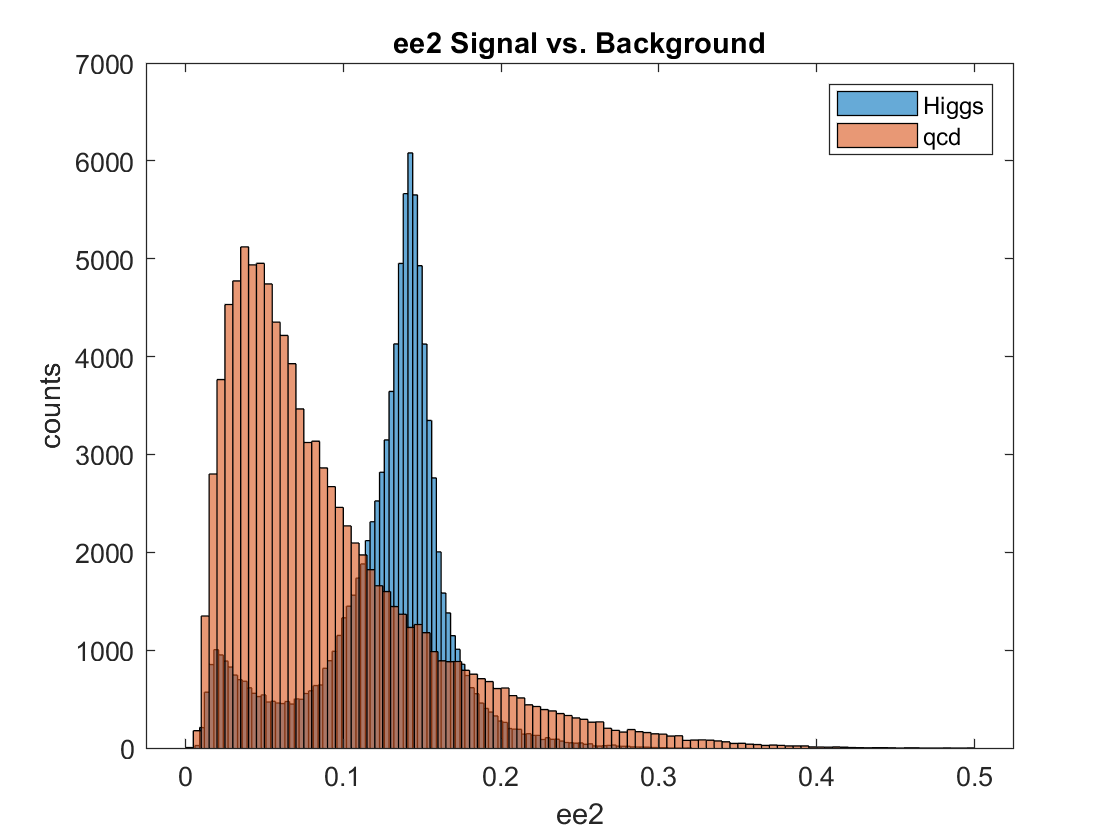

% histogram(d2_h)
% hold on
% histogram(d2_q)

% title('d2 Signal vs. Background')
% xlabel('d2')
% ylabel('counts')
% legend('Higgs','qcd')
% hold off

Like the ee3 histograms, the d2 distributions peak near 0 and trail off to the right. Discrimination seems unlikely, though the Higgs data is sharper than the background. 

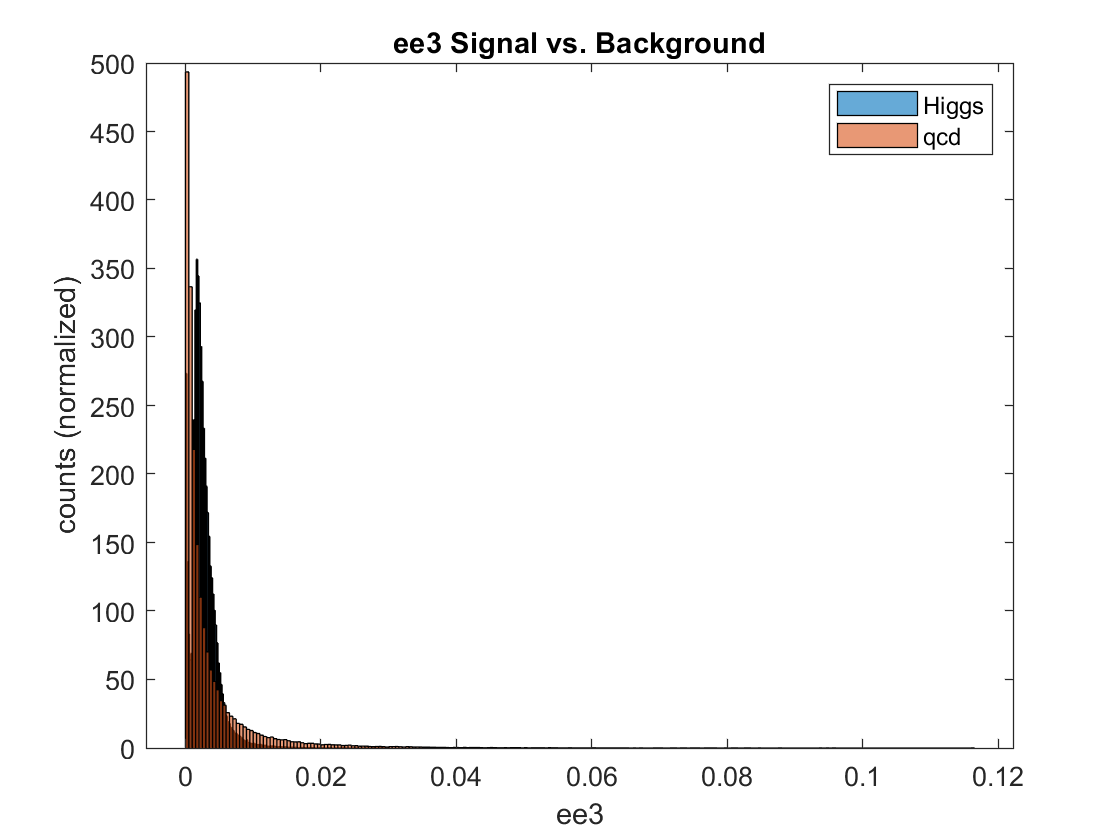

% histogram(angularity_h,'Normalization','pdf')
% hold on
% histogram(angularity_q,'Normalization','pdf')
% title('Angularity Signal vs. Background')
% xlabel('Angularity')

% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

The shape of the angularity distributions is similar to the shapes of ee3 and d2, with the tall peak near zero and the tail to the right. Similarly to those two features, the Higgs and qcd data seem too similar to properly differentiate. The slopes of the two distributions also change, so they intersect at various points. 

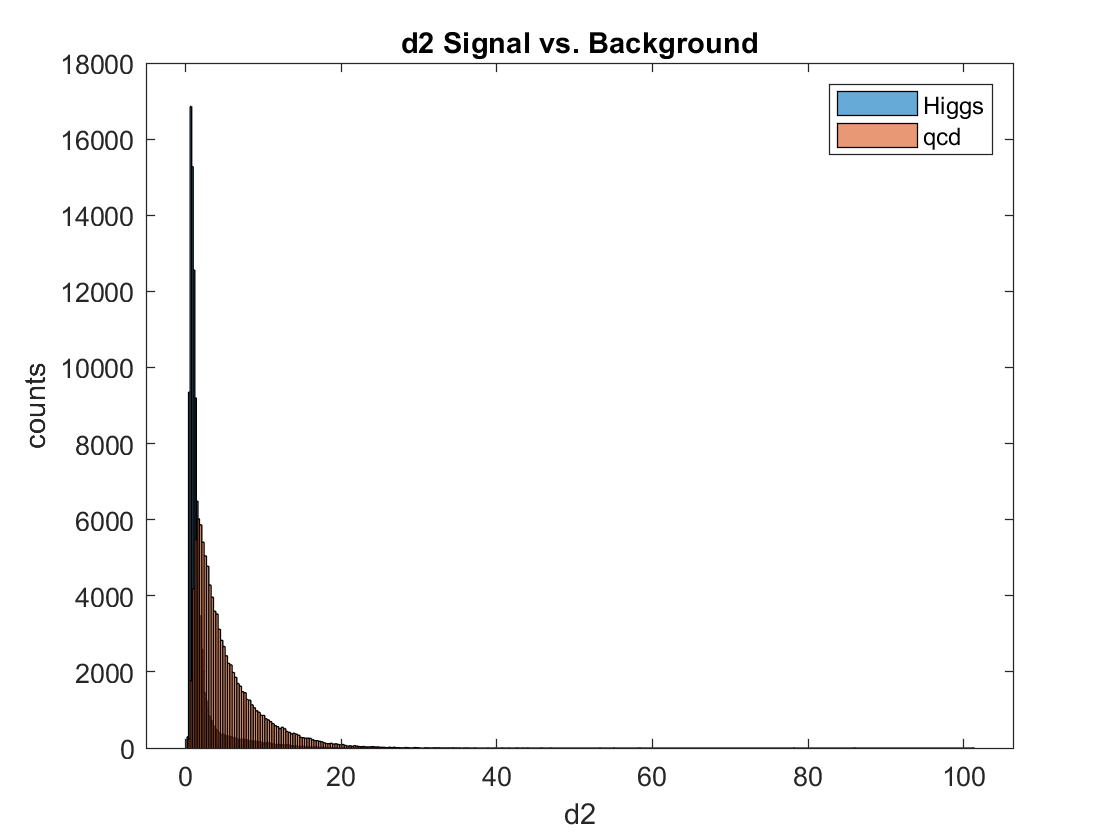

% histogram(t1_h,'Normalization','pdf')
% hold on
% histogram(t1_q,'Normalization','pdf')
% title('t1 Signal vs. Background')
% xlabel('t1')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')

% hold off

There is frequent overlap in the Higgs and qcd datasets for 1-subjettiness. Both peak near t1 = 1 and have narrow distributions. Discrimination would be difficult. 

% histogram(t2_h,'Normalization','pdf')
% hold on
% histogram(t2_q,'Normalization','pdf')
% title('t2 Signal vs. Background')
% xlabel('t2')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

The Higgs and qcd datasets for 2-subjettiness are distinguishable. While both lie on the interval t2 = [0,1] for the most part, the Higgs and background peaks are on opposite ends of that spectrum, and they have very different distribution shapes. 

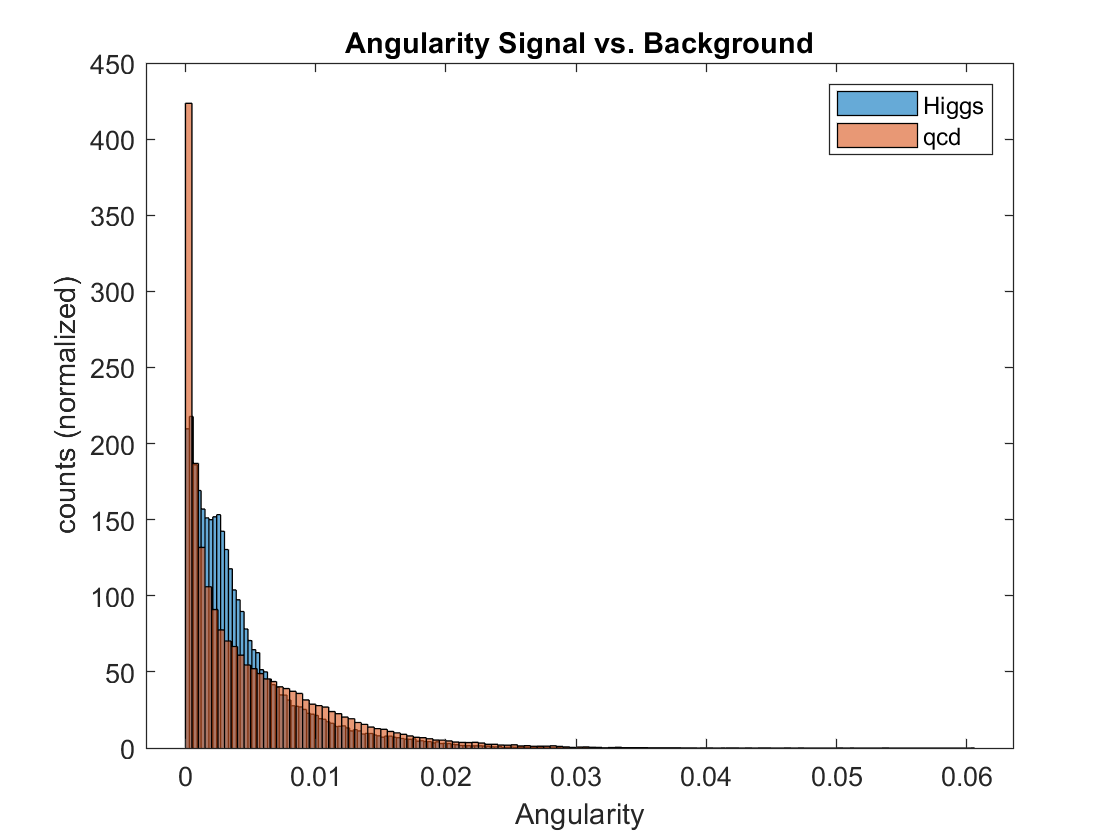

% histogram(t3_h,'Normalization','pdf')

% hold on
% histogram(t3_q,'Normalization','pdf')
% title('t3 Signal vs. Background')
% xlabel('t3')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

The 3-subjettiness distributions are very similar to t2, with the different peak values and distribution shapes. Also distinguishable. 

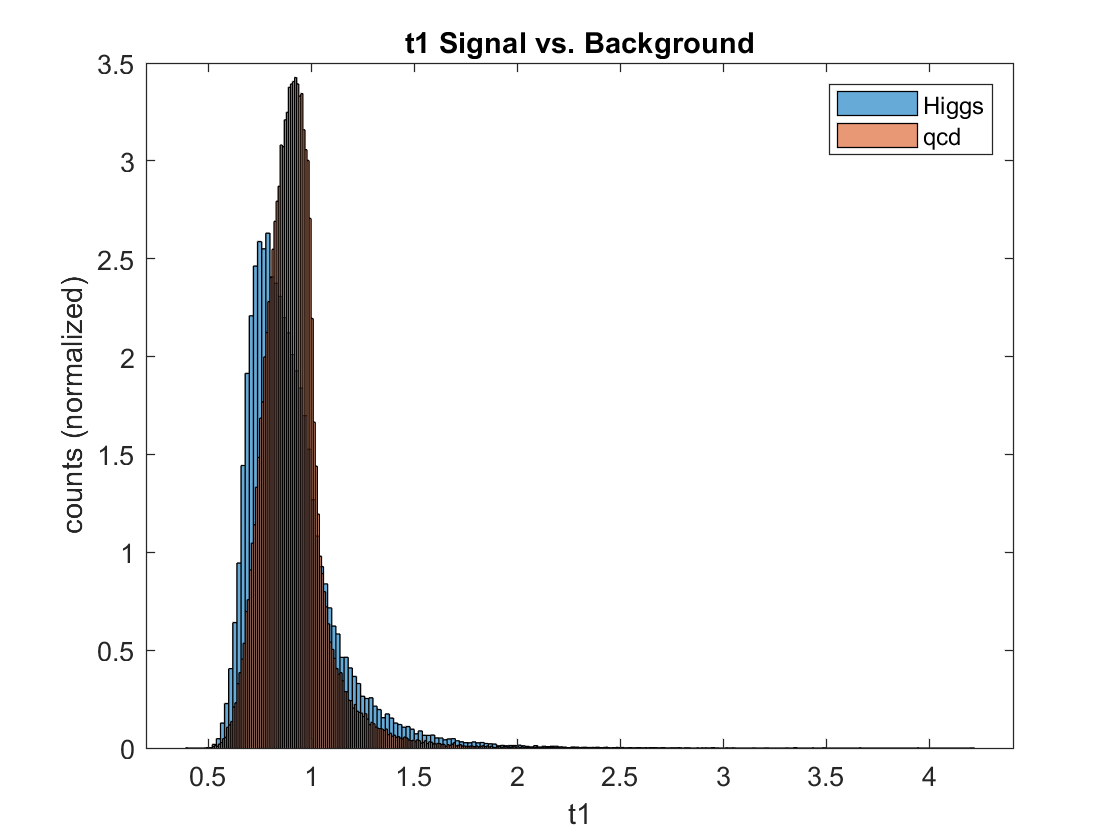

% histogram(t21_h,'Normalization','pdf')
% hold on
% histogram(t21_q,'Normalization','pdf')

% title('t21 Signal vs. Background')
% xlabel('t21')
% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

Also very distinguishable! The distributions for the ratios of 2- and 1-subjettiness look almost like a bow-tie. 

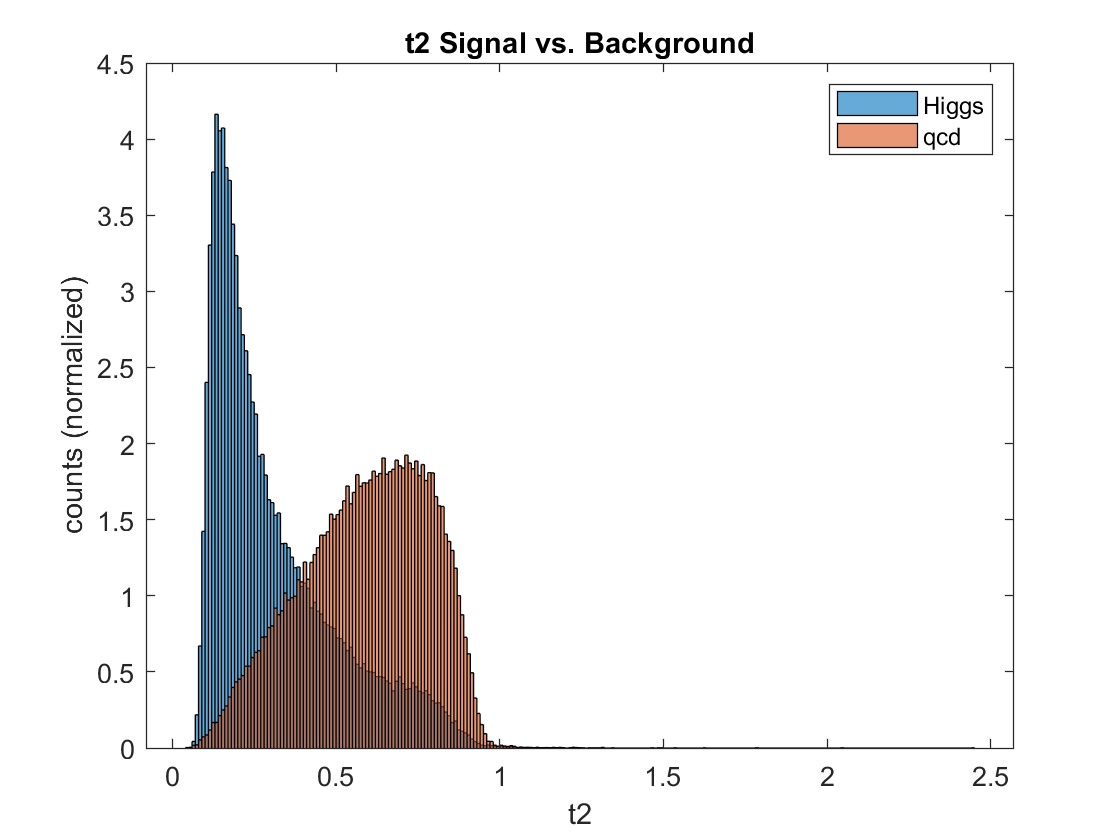

% histogram(t32_h,'Normalization','pdf')
% hold on
% histogram(t32_q,'Normalization','pdf')
% title('t32 Signal vs. Background')
% xlabel('t32')

% ylabel('counts (normalized)')
% legend('Higgs','qcd')
% hold off

Alas, the record of discrimination between Higgs and background data comes to an end. These distributions for the ratios of 3- and 2-subjettiness are very similar. 

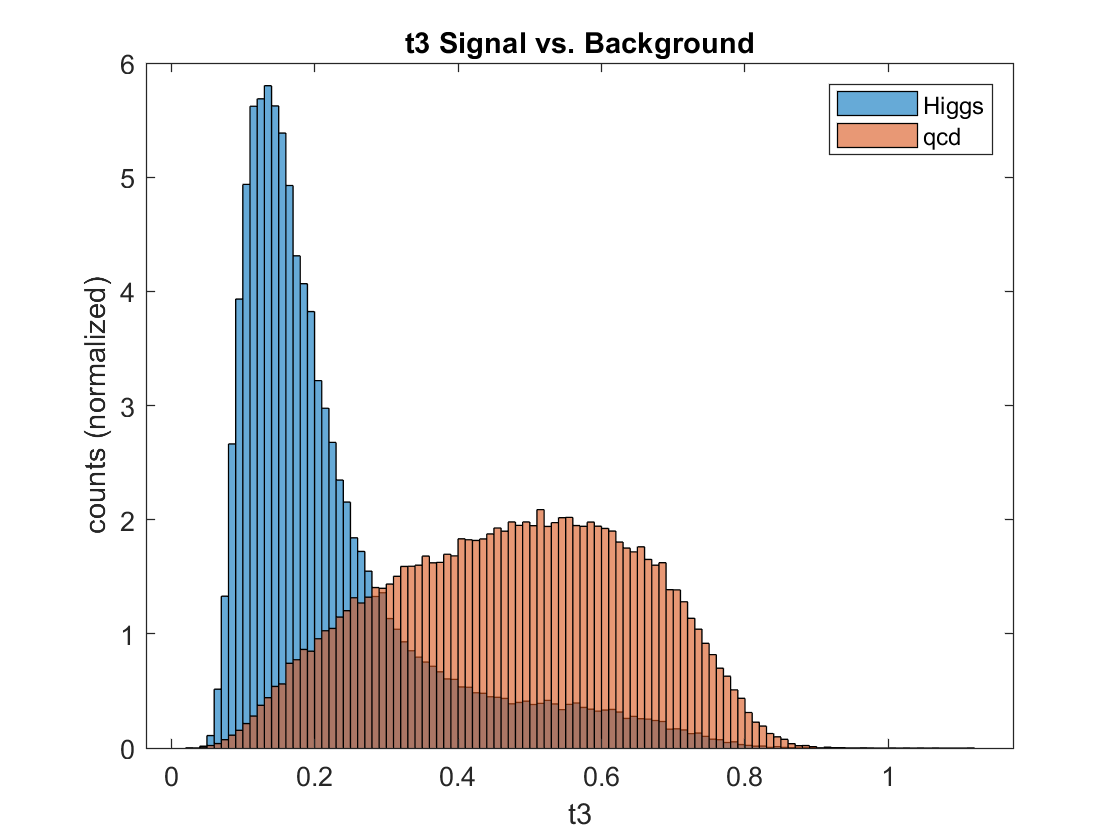

% histogram(KtDeltaR_h)
% hold on
% histogram(KtDeltaR_q)
% title('KtDeltaR Signal vs. Background')
% xlabel('KtDeltaR')
% ylabel('counts')
% legend('Higgs','qcd')

% hold off

I'd rate these distinguishable. The two distributions have different peak values, although the Higgs data does also have a smaller secondary peak near the peak of the background. Also, they both have tails to the right. Overall though, sufficiently different. 

### Summary:

Not all features provide discrimination between signal and background. Here is a list of my findings:

*Discriminatory:*

pT, eta, mass, ee2, t2, t3, t21, KtDeltaR

*Non-Discriminatory:*

phi, ee3, d2, angularity, t1, t32

## 2. Correlations Among Features

<use the equations to predict correlations>

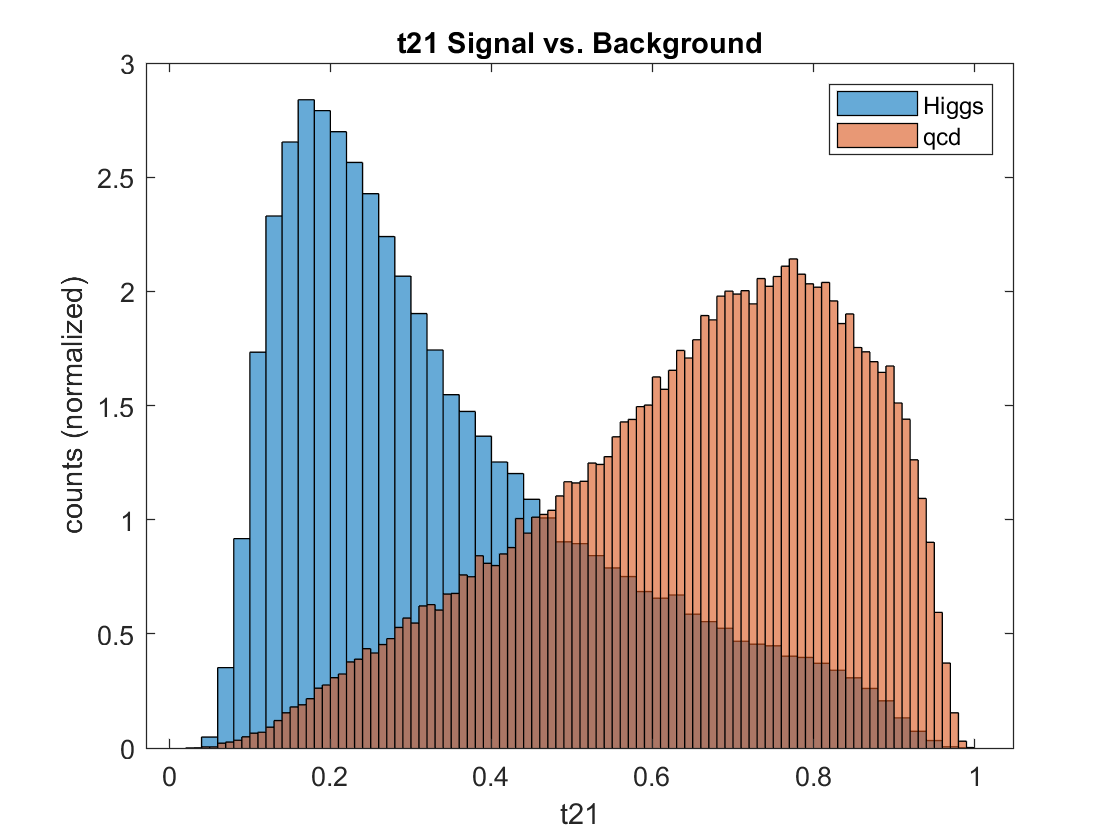

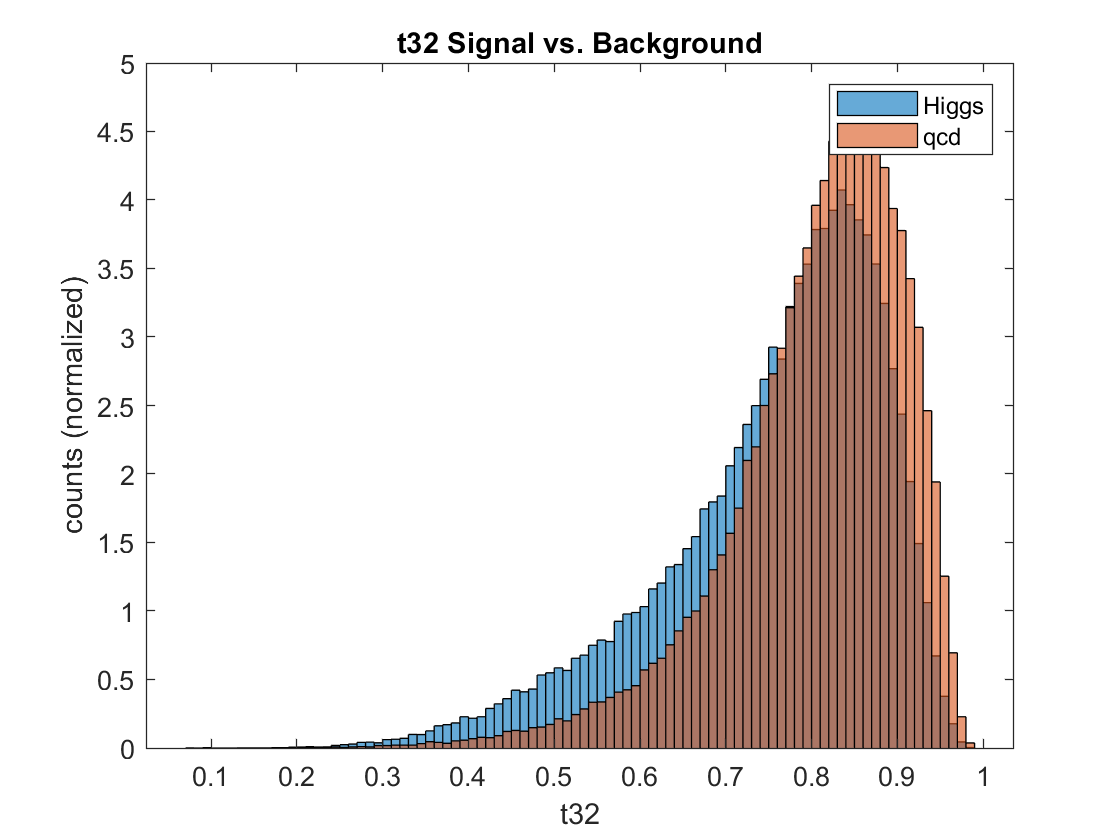

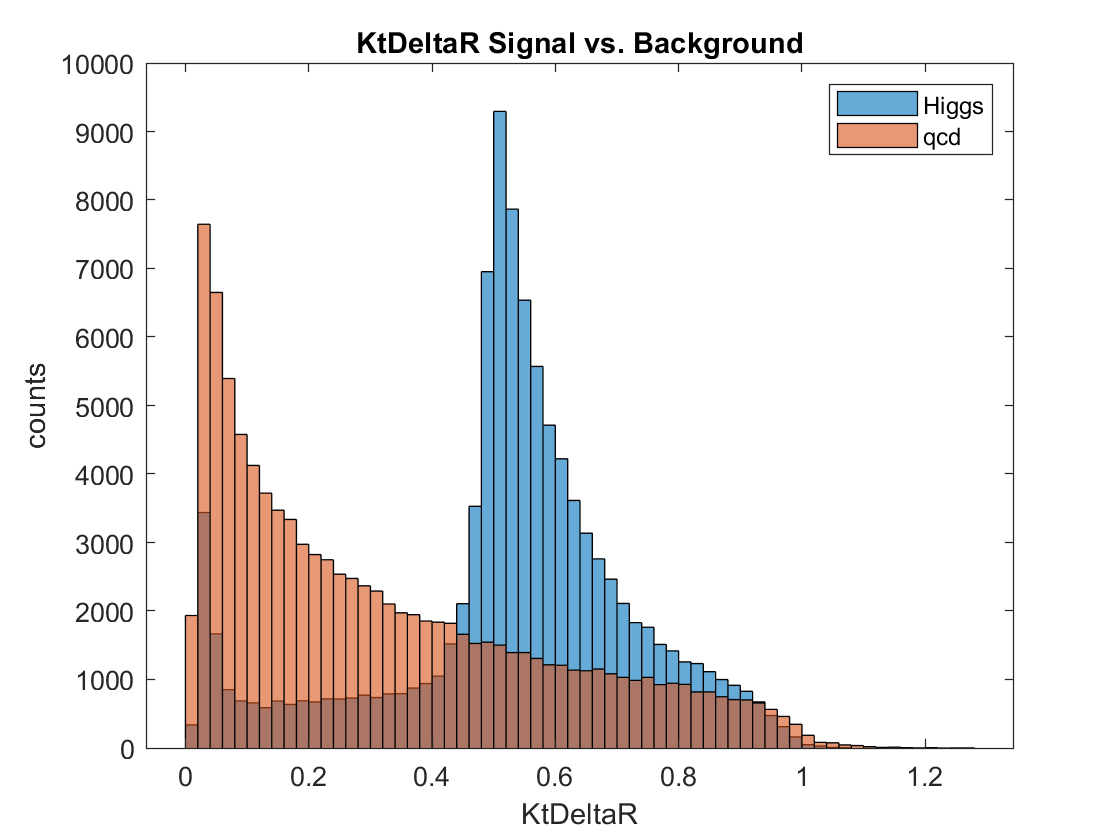

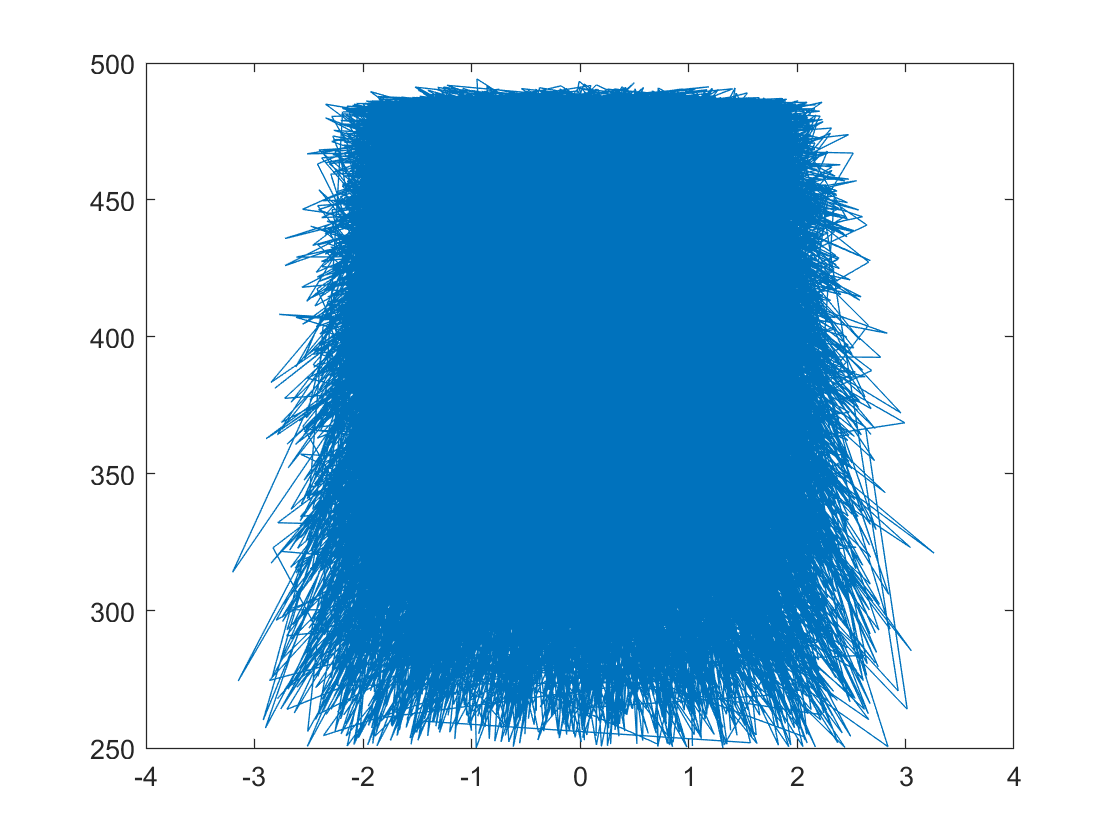

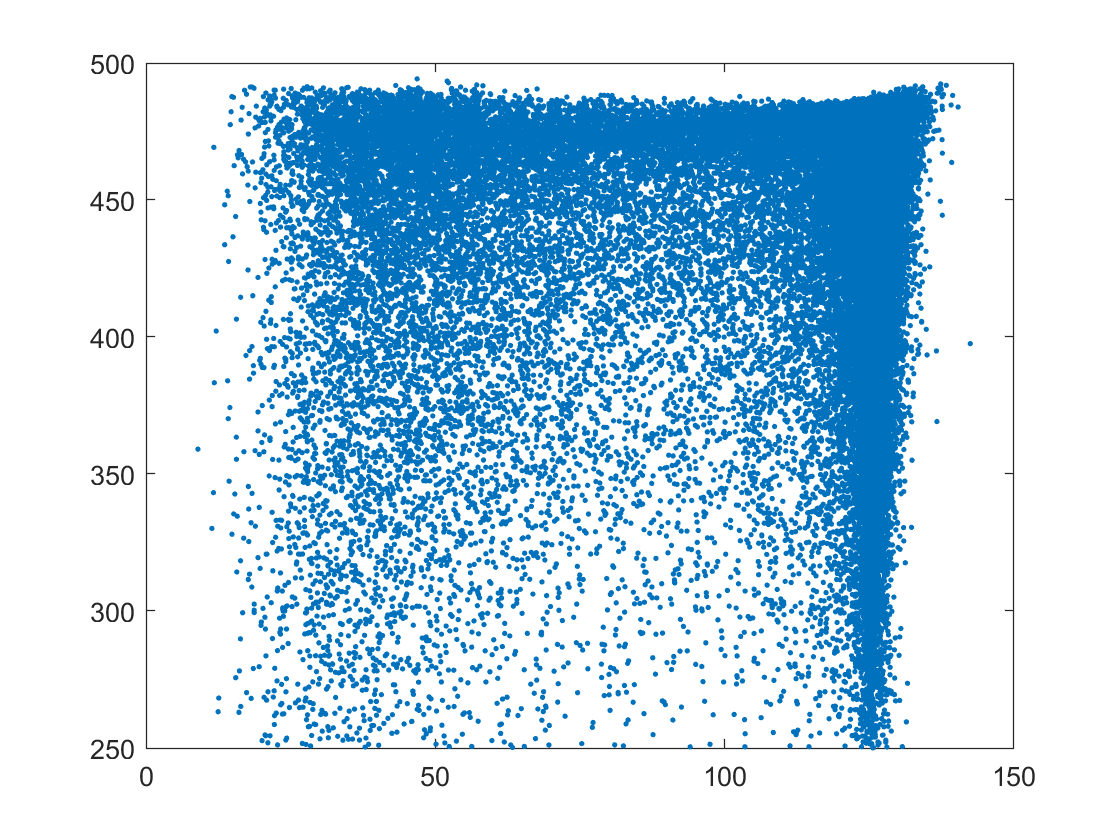

Error using scatterhist (line 189)
NBINS must be a positive integer or a vector of two positive integers, or a cell array of at most two cells of positive integers.

plot(eta_h,pt_h)

plot(mass_h,pt_h,'LineStyle','none','Marker','.')
scatterhist(mass_q,pt_q,'NBins',50)

## 3. Computing Expected Discovery Sensitivity

<normalize each sample appropriately>

## 4. Plan for Optimization of Discovery Sensitivity

<apply selections to these features>